# Sapphire Quick Look

## Setup

%addpath(genpath("C:\Users\00011114\Documents\MATLAB"));
%addpath(genpath("C:\Users\00011114\Documents\ArduinoMatlab"));
addpath("C\Users\00011114\Documents\SapphireMini\Matlab\mseedlib");

clear variables
[file,path]=uigetfile(".msd","Select miniseed input file",'MultiSelect',"on");
fname = fullfile(path,file);
samprate = 16;

Cat the miniseed blocks together to build the structure

X=[];
if(strcmp(class(fname),'char'))
    fname = {fname};
end

for k=1:length(fname)
    d = dir(fname{k});
    if(d.bytes > 0)
        fprintf("Loading %s\n",fname{k})
        XX=rdmseed(fname{k});
        indx_zero = [XX.NumberSamples]==0;
        XX(indx_zero)=[];
        X = cat(2,X,XX);
        ftime(k) = XX(1).t(1);
    end
end

Loading F:\S502N024.msd


This section extracted from rdmseed to build the index blocks

un = unique(cellstr(char(X.ChannelFullName)));
nc = numel(un);
for i = 1:nc
    k = find(strcmp(cellstr(char(X.ChannelFullName)),un{i}));
    I(i).ChannelFullName = X(k(1)).ChannelFullName;
    I(i).XBlockIndex = k;
    I(i).ClockDrift = ([diff(cat(1,X(k).RecordStartTimeMATLAB));NaN]*86400 - cat(1,X(k).NumberSamples)./cat(1,X(k).SampleRate))./cat(1,X(k).NumberSamples);
    I(i).OverlapBlockIndex = k(find(I(i).ClockDrift.*cat(1,X(k).NumberSamples).*cat(1,X(k).SampleRate) < -.5) + 1);
    I(i).OverlapTime = cat(1,X(I(i).OverlapBlockIndex).RecordStartTimeMATLAB);
    I(i).GapBlockIndex = k(find(I(i).ClockDrift.*cat(1,X(k).NumberSamples).*cat(1,X(k).SampleRate) > .5) + 1);
    I(i).GapTime = cat(1,X(I(i).GapBlockIndex).RecordStartTimeMATLAB);
end
BDFIndx = find(~cellfun(@isempty,strfind({I.ChannelFullName},'BDF')));
samprate = X(I(BDFIndx).XBlockIndex(1)).SampleRate

samprate = 16

check for missing samples

for k=1:(nc-1)
    xindx = I(k).XBlockIndex;
    nsamples = [X(xindx).NumberSamples]';
    tstart= reshape([X(xindx).RecordStartTimeISO],22,[])';
    tstartd = datetime(tstart,'InputFormat','uuuu-DDD HH:mm:ss.SSSS');
    clockDrift{k} = I(k).ClockDrift;
    badtimes = find(tstartd<datetime('02/02/2022','InputFormat','MM/dd/uuuu'));
    if(~isempty(badtimes))
        badtimes(end+1) = 1 + badtimes(end);
        tstartd(badtimes) = [];
        nsamples(badtimes)= [];
        clockDrift{k}(badtimes) = [];
    end
    deltaSamps{k} = nsamples(1:end-1) - round(samprate*seconds(diff(tstartd)));
end
minElements = min(cellfun(@length,deltaSamps));
if(any(cellfun(@any,deltaSamps)))
    warning("Sample Time Jumps!!");
else
    fprintf("Sample Time is continuous");   
end

Sample Time is continuous

OK, now load the data.  This will be all the channels except the logIndex channel

clear NumSamples TimeCorrection DataQuality x t ix
logIndx = find(~cellfun(@isempty,strfind({I.ChannelFullName},'LOG')));
minsamps = inf;
for k=1:length(I)
    if(k == logIndx)
        continue;
    end
    ix = I(k).XBlockIndex;
    fprintf("Channel: %s\n",I(k).ChannelFullName)
    seqNum = str2num(char(X(ix).SequenceNumber));
    NumSamples{k}     = [X(ix).NumberSamples];
    TimeCorrection{k} = [X(ix).TimeCorrection];
    DataQuality{k}    = [X(ix).DataQualityFlags];
    xx{k}                  = cat(1,X(ix).d);
    tt{k}                  = cat(1,X(ix).t);
    nsamps = size(xx{k},1);
    minsamps = min(minsamps,nsamps);
end

Channel: ZZ:SM502:00:BDE
Channel: ZZ:SM502:00:BDF
Channel: ZZ:SM502:00:BDK
Channel: ZZ:SM502:00:BDL


if(exist('xx')==0)
    fprintf("NO DATA FRAMES!!")
    return;
end
for k=1:length(xx)
    xx{k}=xx{k}(1:minsamps);
    tt{k}=tt{k}(1:minsamps);
end

t = cat(2,tt{:});
x = cat(2,xx{:});

logIndx = find(~cellfun(@isempty,strfind({I.ChannelFullName},'LOG')));
if(isempty(logIndx))
    warning("No Log Files");
else
    ix = I(logIndx).XBlockIndex;
    logtext = cat(2,X(ix(1:end)).d); %%skip log sections for now
    logtime = cat(2,X(ix(1:end)).t);
    logtext = erase(logtext,char(0)); %drop the null pad
    logopen = strfind(logtext,'{');
    logopen = logopen(1);
    logclose = strfind(logtext,'}');
    logclose = logclose(end);
    logtext = logtext(logopen:logclose);
    logjson = ['{"log":[' strrep(logtext,'}{','},{') ']}'];

    z = jsondecode(logjson);
end

if(~isempty(logIndx))
    clear power gps;
    for k=1:length(z.log)
        f1 = fieldnames(z.log{k});
        switch(f1{1})
            case 'power'
                power(k) = z.log{k}.power;
            case 'gps'
                gps(k)   = z.log{k}.gps;
            otherwise
                error('Unknow JSON in log file');
        end
    end
end

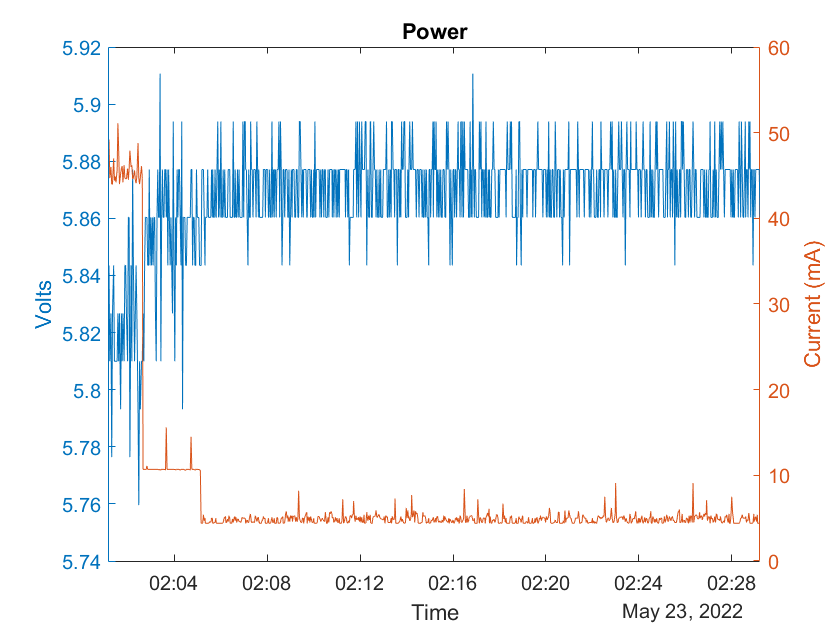

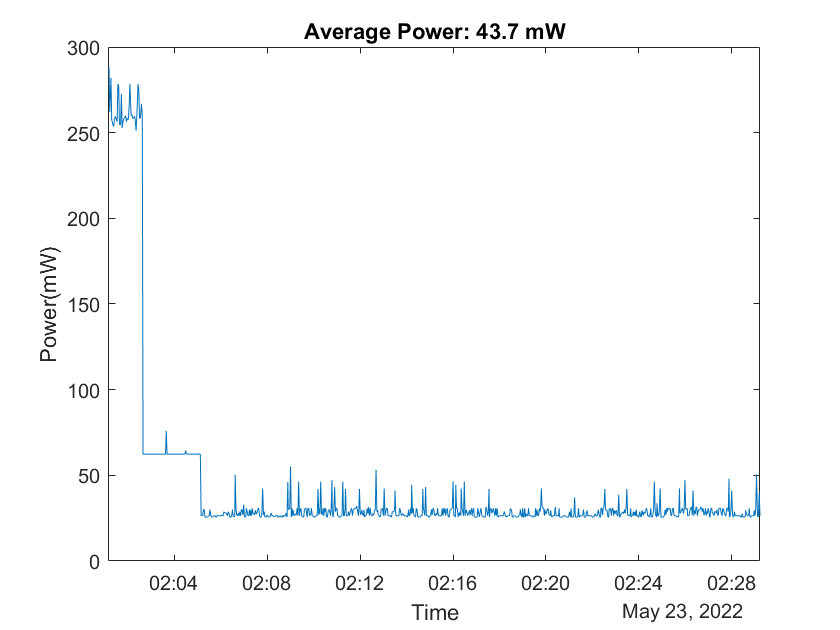

% power system power
if(~isempty(logIndx))
    figure
    powerTime = datetime([power.Time],'convertFrom','posixtime');
    indx = find(powerTime > datetime('01-Feb-2022 00:00:00'));

    yyaxis left
    plot(powerTime,[power.batVolt])
    title('Power')
    xlabel('Time');
    ylabel('Volts')
    yyaxis right
    plot(powerTime,[power.current_mA]);
    ylabel('Current (mA)');
    xlim([powerTime(indx(1)) powerTime(indx(end))])
    % calculate power use
    figure
    plot(powerTime,[power.power_mW]);
    xlabel('Time');
    ylabel('Power(mW)');
    title('Power Use')
    xlim([powerTime(indx(1)) powerTime(indx(end))])

    deltaT = diff(powerTime);
    deltaT(deltaT>seconds(1000)) = 0;   %clip off anything too long
    power_mW = [power.power_mW];
    energy = sum(power_mW(1:end-1) .* seconds(deltaT)) / sum(seconds(deltaT));
    title(sprintf('Average Power: %.1f mW',energy));
end


gpsnotnull =

     []



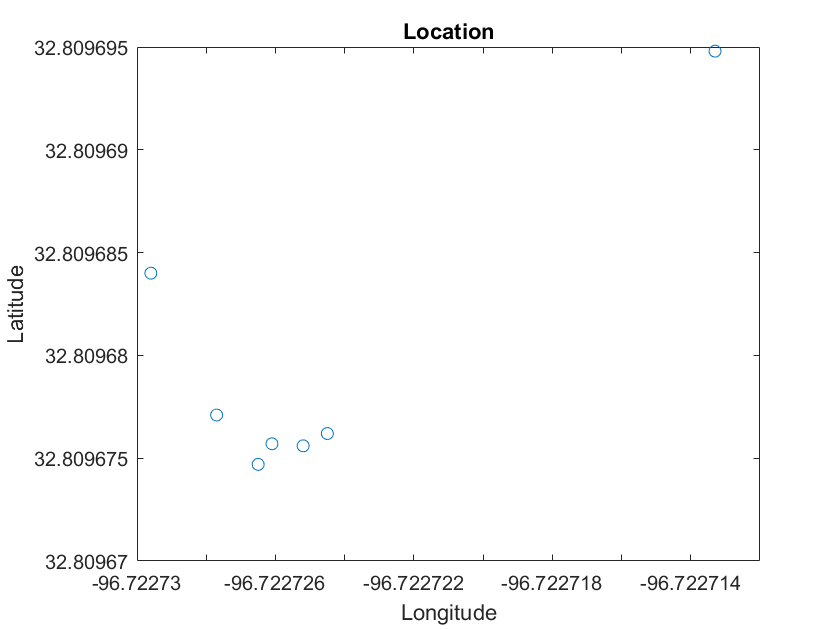

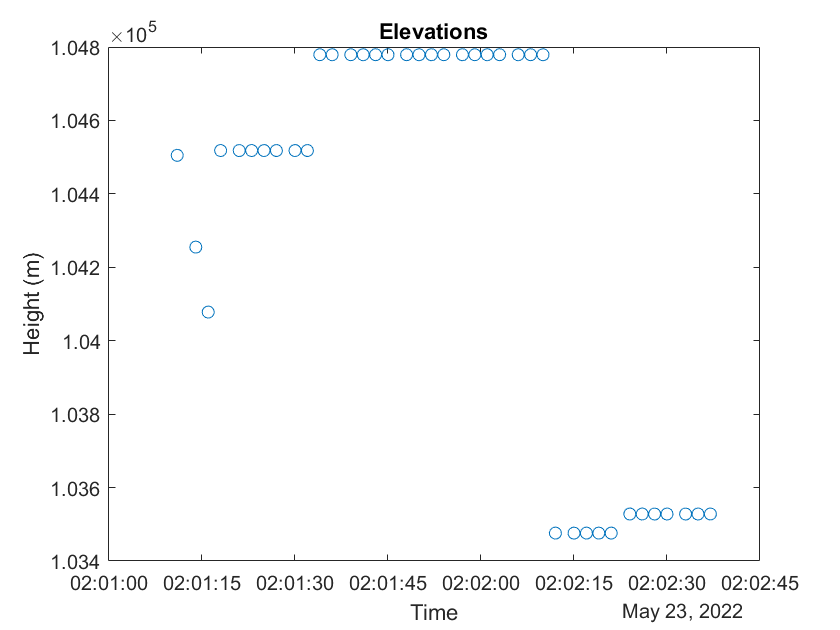

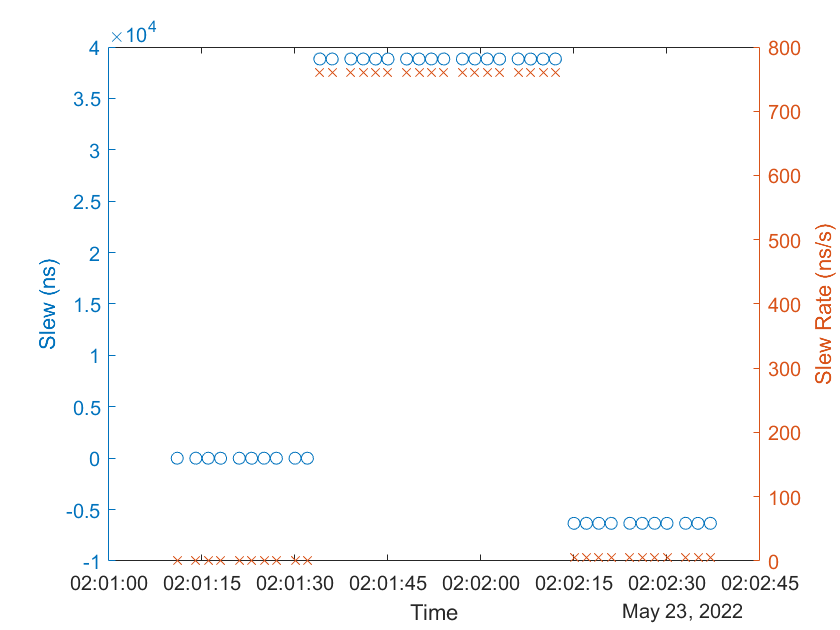

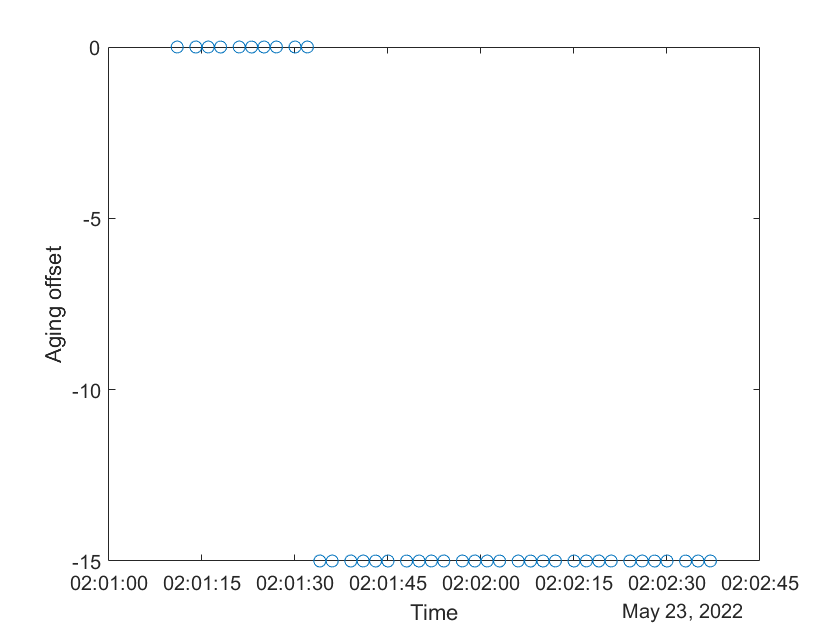

%We need a GPS plot here, but so far don't have data with a lock
if(~isempty(logIndx))
    gpsnotnull = gps.Time
    gpsTime = datetime([gps.Time],'convertFrom','posixtime');
    indx    = find(gpsTime > datetime('01-Feb-2022 00:00:00'));
    goodtimes = gpsTime(indx([1 end]));
    lat = [gps.Lat];
    lon = [gps.Lon];
    slew= [gps.Slew];
    slewrate = [gps.SlewRate];
    aging = [gps.Aging];
    height = [gps.Height];
    gpsgood = find((lat~=0) & (lon~=0) & (gpsTime>datetime('01-Feb-2022 00:00:00')));
    lat = lat(gpsgood);
    lon = lon(gpsgood);
    height = height(gpsgood);
    slew = slew(gpsgood);
    slewrate = slewrate(gpsgood);
    aging = aging(gpsgood);
    gpstimes = gpsTime(gpsgood);
    figure

    plot(lon/1e7,lat/1e7,'o')
    title('Location');
    xlabel('Longitude');
    ylabel('Latitude');

    figure
    plot(gpstimes,height,'o');
    title('Elevations');
    xlabel('Time');
    ylabel('Height (m)')

    figure
    yyaxis left
    plot(gpstimes,slew,'o');
    ylabel('Slew (ns)')
    yyaxis right
    plot(gpstimes,slewrate,'x');
    ylabel('Slew Rate (ns/s)')
    xlabel('Time')

    figure
    plot(gpstimes,aging,'o');
    ylabel('Aging offset');
    xlabel('Time')
end

%plot the data
figure
chanNames = unique({I.ChannelFullName});
sampleTime = datetime(t,'ConvertFrom','datenum');
goodtimes = find(sampleTime(:,1) > datetime('01-Feb-2022 00:00:00'));
goodtimes = sampleTime(goodtimes([1 end]),1);
missingSamps = x==-128;
xp = x;
xp(missingSamps) = NaN;   %clean up the missing samples

plot(sampleTime(:,3:4),xp(:,3:4));
hold on;
v = ylim;
%plot(datetime([ftime;ftime],'ConvertFrom','datenum'),repmat(v',1,length(ftime)),'--r');
% if(sum(missingSamps(:,3))>0)
%     plot(sampleTime(find(missingSamps(:,3))),20,'rx');
% end
% if(sum(missingSamps(:,4))>0)
%     plot(sampleTime(find(missingSamps(:,4))),21,'ro');
% end
hold off;
legend('BDK','BDL');
xlabel('Time')
ylabel('Temperature (degC)')
set(gca,'XTickLabelRotation',45)
if(sum(missingSamps(:,1))==0)
    fprintf("No missing samples!")
else
    fprintf('All Channels: %d missing samples\n',sum(missingSamps(:,1)));
    fprintf(' Missed sample rate: %.2f per 10000 samples',10000*sum(missingSamps(:,1))/length(x));
    fprintf(' Missed sample rate 1 sample/%.1f minute',length(x)/samprate/sum(missingSamps(:,1)));
end

No missing samples!

fprintf('BDK: %d overrange samples\n',sum(isnan(x(:,3))))

BDK: 0 overrange samples


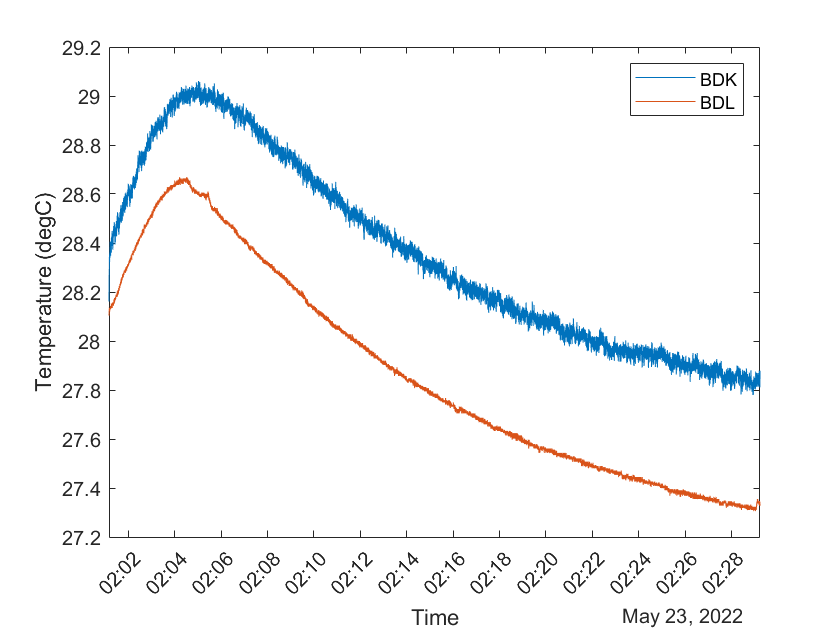

xlim(goodtimes);

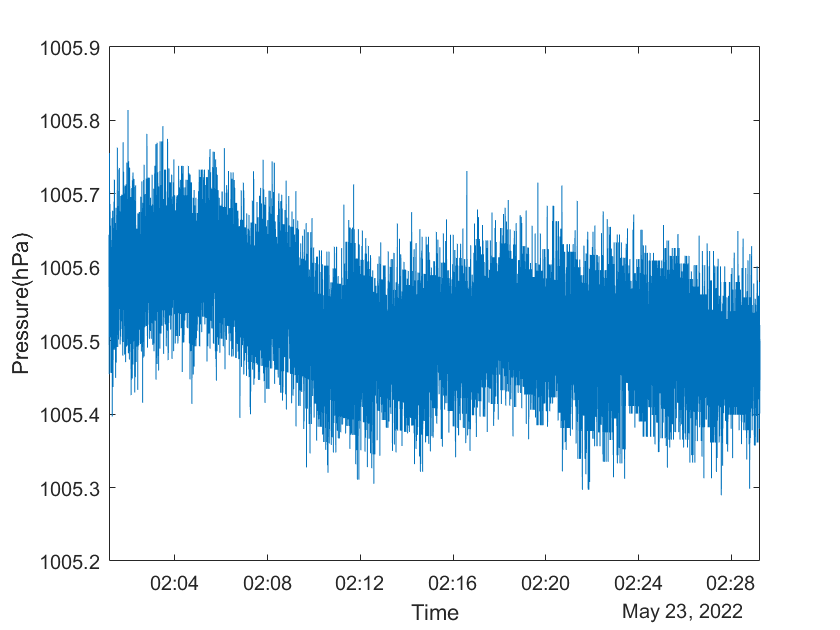


% plot the pressure data
figure
plot(sampleTime(:,1),xp(:,1));
xlabel('Time');
ylabel('Pressure(hPa)')
xlim(goodtimes);

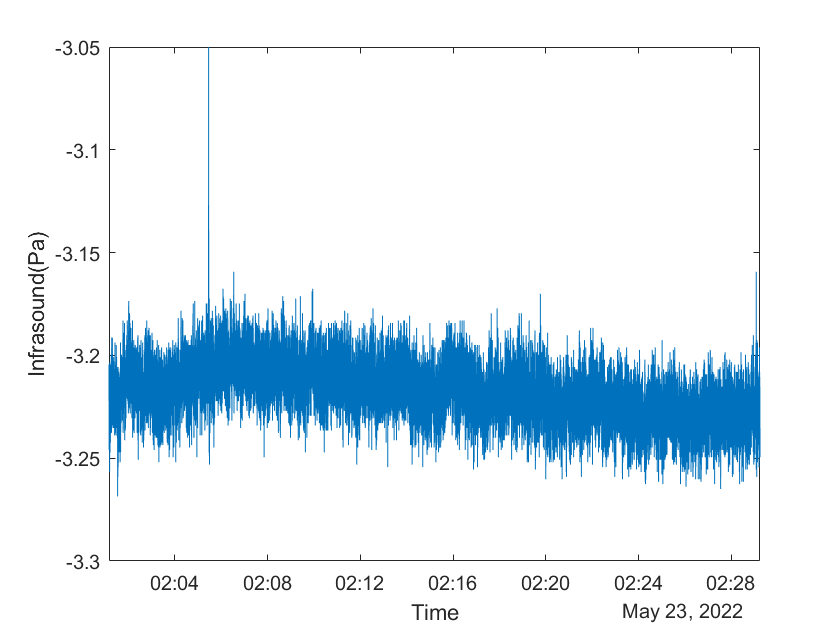


xnan = isnan(x(:,2))*100;
xnan(xnan==0) = NaN;
xnan(xnan==100) = 0;
figure
h=plot(sampleTime(:,2),[-xp(:,2) xnan]);
set(h(2),'LineWidth',4)
xlabel('Time');
ylabel('Infrasound(Pa)')
xlim(goodtimes);

Look for 1pps from GPS

win = hamming(samprate*10);
hop = samprate;
fs = samprate;
refchan = 3;
[C, q, t2] = cepstrogram(x(:,refchan), win, hop, fs);
[~,cindx] = min(abs(q-1));
figure
plot(t2/60,abs(C(cindx,:)));
title("Cepstral 1 second pps");
xlabel("Time from start (min)")'

ans =   Text (Time from start (min)) with properties:

                 String: 'Time from start (min)'
               FontSize: 11
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [0.1500 0.1500 0.1500]
    HorizontalAlignment: 'center'
               Position: [15.0000 -0.0070 -1.0000]
                  Units: 'data'

  Show all properties


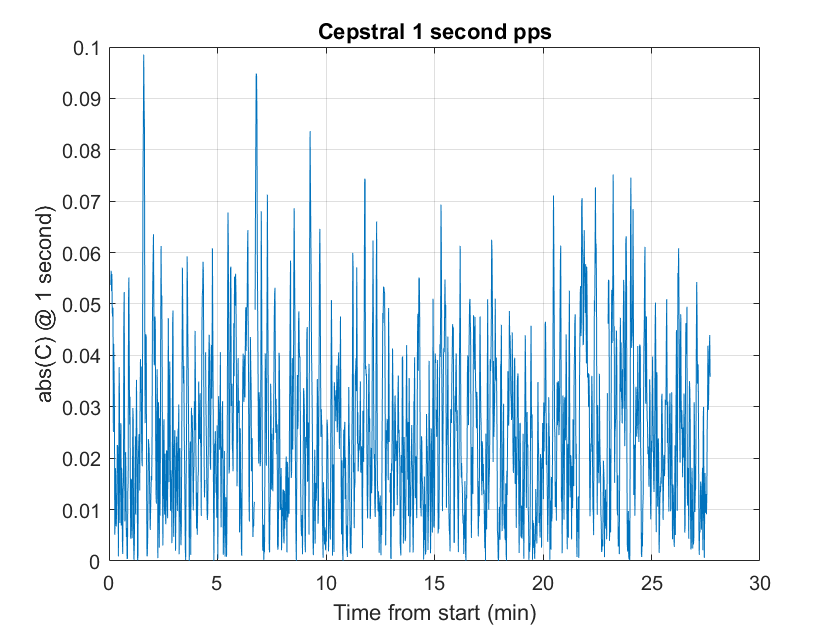

ylabel("abs(C) @ 1 second)");
grid on;

C(cindx,isinf(C(cindx,:)))=0;
ppsSegs = abs(C(cindx,:))' > 0.5;
ppsSegd = diff([0;ppsSegs]);
ppsStart = find(ppsSegd>0.5);
ppsEnd   = find(ppsSegd<-0.5);
nsegs    = min(length(ppsStart),length(ppsEnd));
ppsSegI  = [ppsStart(1:nsegs) ppsEnd(1:nsegs)];

ppsWins  = ppsSegI*hop;
ppsnSegs = diff(ppsSegI');

Check each channel for delta offset from adjacent channels


for seg = 1:size(ppsWins,1);
    tstart = t(ppsWins(seg,1),refchan);
    tend   = t(ppsWins(seg,2),refchan);
    sampdelta = round(samprate*86400*(t(ppsWins(seg,1),refchan)-t(ppsWins(seg,1),:)));
    tindx = ppsWins(seg,1):ppsWins(seg,2)-1;
    tseg = t(tindx,refchan);
    tfrac = abs(tseg*86400 - round(tseg*86400));
    [~,zindx] = min(tfrac); %find the offset to a second
    zindx = mod(zindx-1,samprate); %get it back to the first offset
    xr = reshape(x(tindx,refchan),samprate,ppsnSegs(seg));
    npts(seg) = median(sum(xr<0));
    onepulse = ones(samprate,1);
    pindx = mod((1:npts(seg))+zindx-1,samprate)+1;
    onepulse(pindx) = -1;
    segpulse = repmat(onepulse,ppsnSegs(seg),1);

    for chan=1:4
        xr = reshape(x(sampdelta(chan)+tindx,chan),samprate,ppsnSegs(seg));
        xc(:,chan,seg) = xcorr(segpulse,x(sampdelta(chan)+tindx,chan),samprate/2,'coeff');
        [~,xcm(chan,seg)] = max(abs(xc(:,chan,seg)));
        clf;plot(onepulse*500);hold on;plot(xr);hold off;drawnow;
    end
end
figure
plot(xcm');

Unrecognized function or variable 'xcm'.

xlabel("GPS segment");
ylabel('Delta Shift');
legend('BDF','BDE','BDK','BDL')

## Overall spectrum of Infrasound (for noise analysis)

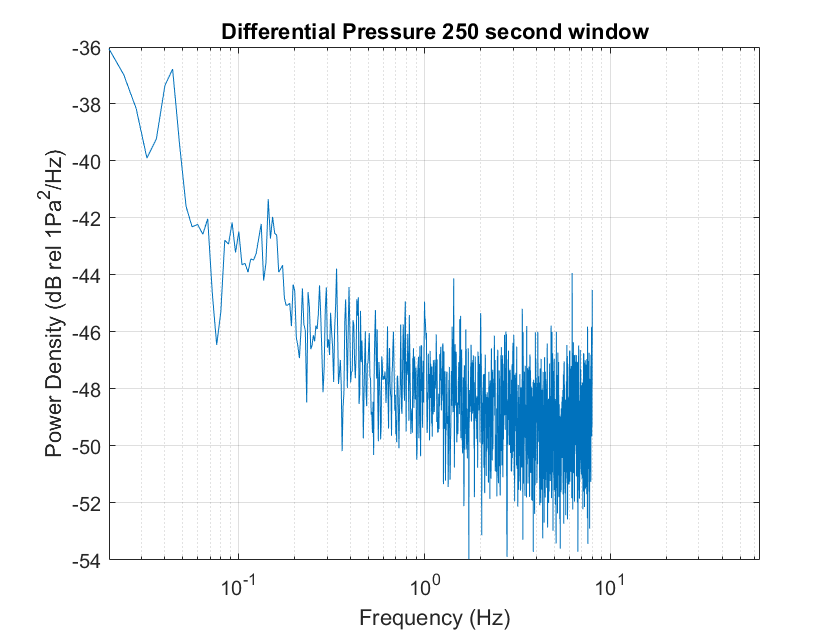

indx = find(sampleTime(:,2)>goodtimes(1) & sampleTime(:,2)<goodtimes(2));
npeaks = 15;

wlen = samprate*250;
[Pxx,F] = pwelch(detrend(double(xp(indx,2))),wlen,wlen/2,wlen,samprate);
figure
semilogx(F,10*log10(Pxx));
grid on;
title('Differential Pressure 250 second window');
ylabel('Power Density (dB rel 1Pa^2/Hz)');
xlabel('Frequency (Hz)');
xlim([0.02 64])

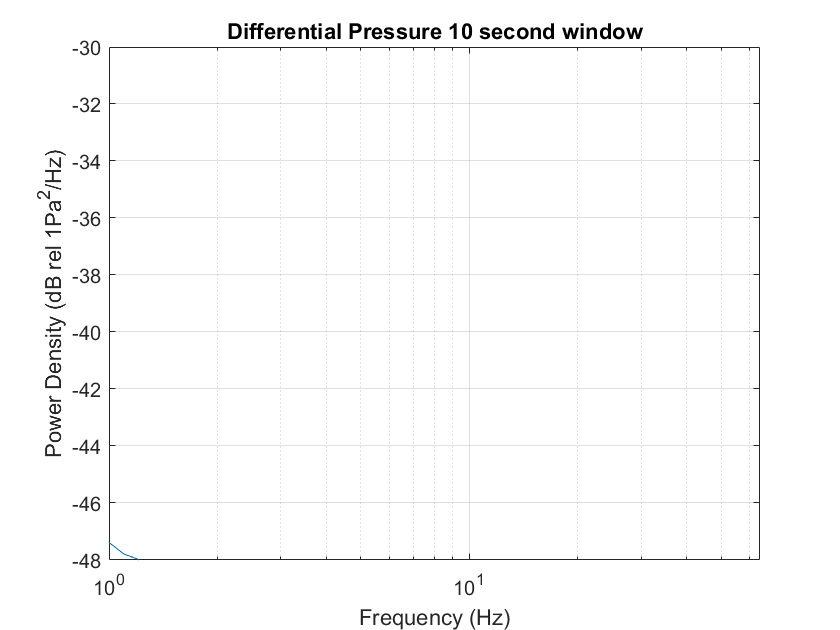


wlen = samprate*10;
[Pxx,F] = pwelch(detrend(double(xp(indx,2))),wlen,wlen/2,wlen,samprate);
figure
semilogx(F,10*log10(Pxx));
xlim([ 1 64]);
grid on;
title('Differential Pressure 10 second window');
ylabel('Power Density (dB rel 1Pa^2/Hz)');
xlabel('Frequency (Hz)');
ylim([-48 -30])

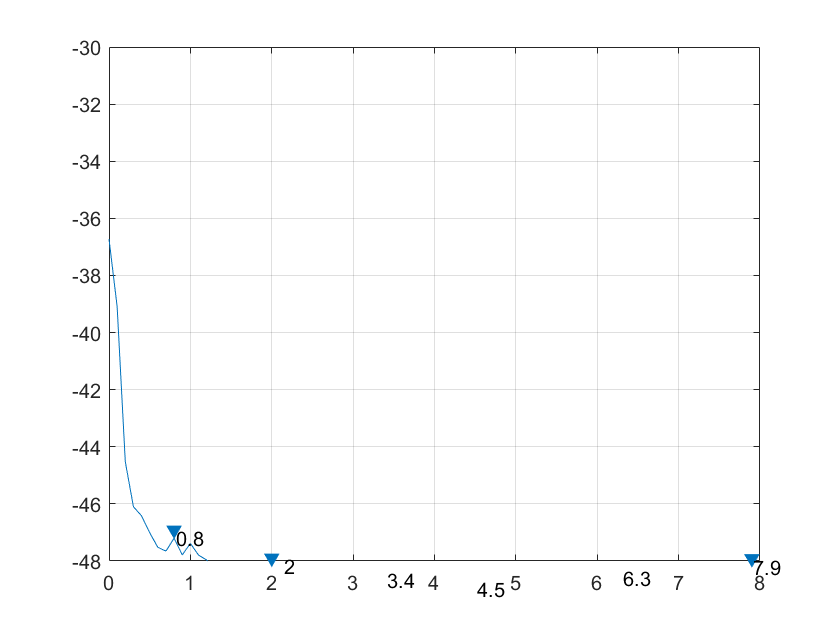


figure
[pks,locs] = findpeaks(10*log10(Pxx),F,'NPeaks',npeaks,'MinPeakDistance',1,'SortStr','descend');
findpeaks(10*log10(Pxx),F,'NPeaks',npeaks,'MinPeakDistance',1,'SortStr','descend');
text(locs+0.02,pks,num2str(locs));
grid on
ylim([-48 -30])